clear r
for i=1:2000
x=randn(6,1);
r(i)=norm(logSE3(expse3(x))-limitToPi_Li(x));
end
max(r)

ans =       3.01285974263075e-14

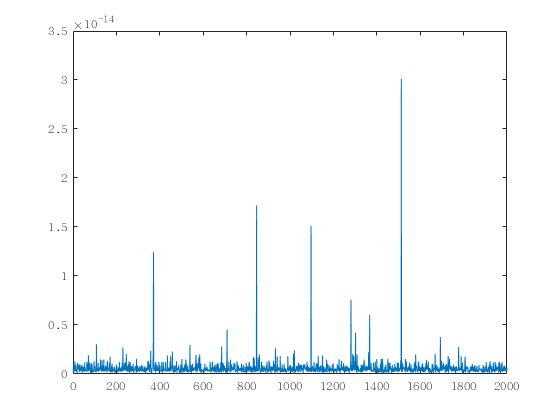

plot(r)

T = [                    0                         0                         1                         0;
       4.9960036108132e-16                        -1                         0      6.10622663543836e-15;
                         1       4.9960036108132e-16                         0                        30;
                         0                         0                         0                         1];

expse3(logSE3(T))

ans =      -4.44089209850063e-16      6.22658702285336e-16                         1      -3.5527136788005e-15
     -1.78569492435273e-16                        -1      6.22658702285336e-16      1.58565132983081e-14
                         1     -1.78569492435273e-16      2.22044604925031e-16                        30
                         0                         0                         0                         1
